# Funcions

#### Anonymous functions

f = @(x)x.^2 + sin(3*x+1)

f = function_handle with value:
    @(x)x.^2+sin(3*x+1)


f(2)

ans = 4.6570

f([2,3,4])

ans =     4.6570    8.4560   16.4202


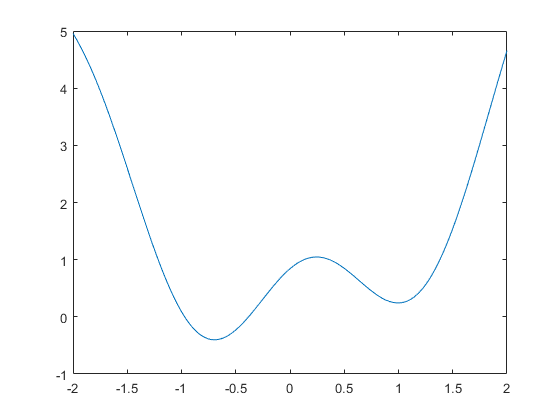

% gràfica
t = [-2:0.01:2];
plot(t,f(t))

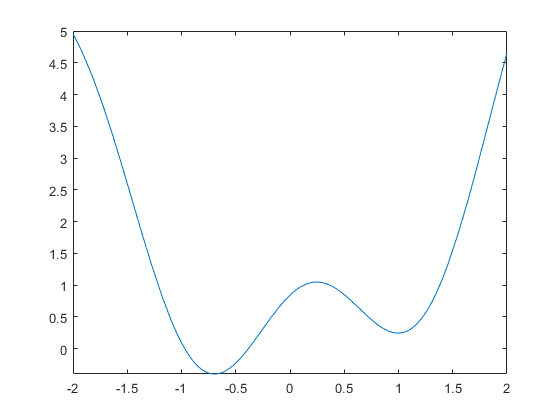

% només per anonymous
fplot(f,[-2,2])

% diverses variables
f = @(x,y,z)x.^2+y.^2+z.^2;
f(1,2,-1)

ans = 6

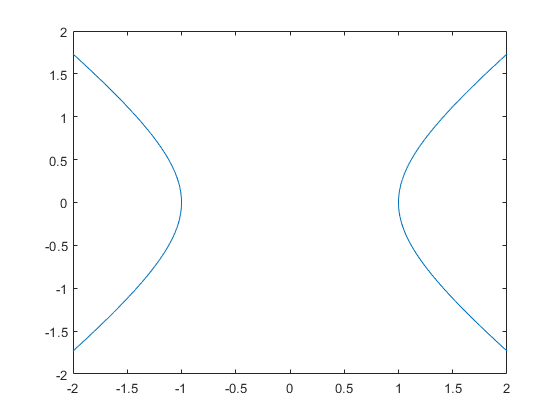

% dues variables
f = @(x,y)x.^2-y.^2-1;
fimplicit(f,[-2,2,-2,2])

# Funcions clàssiques

% error absolut i error relatiu
a = pi;
b = 22/7

b = 3.1429

[ea,er,ep] = funerror(a,b)

ea = 0.0013

er = 4.0234e-04

ep = 0.0402

[~,~,ep] = funerror(a,b)

ep = 0.0402

[dc,xc] = xifres(a,b)

ea = 0.0013

er = 4.0234e-04

ep = 0.0402

d = 2

x = 3

dc = 2

xc = 3

# Funció

function [d,x] = xifres(x,y)
% xifres decimals correctes
[ea,er,ep] = funerror(x,y)
d = fix(-log10(2*ea))
x = fix(-log10(2*er))
end